# Respuesta al impulso (TD)


$$y\left\lbrack n\right\rbrack =T\left\lbrace \delta \left\lbrack n\right\rbrack \right\rbrace =h\left\lbrack n\right\rbrack$$


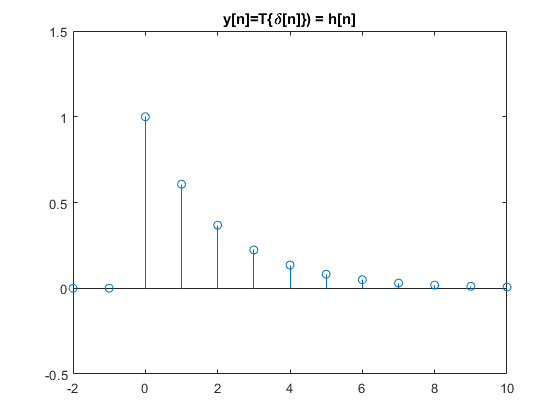

n = -2:10;
h = @(n) exp(-0.5*n).*(n>=0);
figure
clf
stem(n,h(n));
ylim([-0.5,1.5])
title('y[n]=T\{\delta[n]\}) = h[n]')

## Sumatoria de convolución

Si queremos obtener la respuesta de un sistema $y\left\lbrack n\right\rbrack$ a una entrada arbitraria $x\left\lbrack n\right\rbrack$


$$y\left\lbrack n\right\rbrack =T\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =y\left(x\left\lbrack n\right\rbrack \right)$$


por la propiedad de *sifting* tenemos que$x\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack \delta \left\lbrack n-k\right\rbrack$


$$y\left\lbrack n\right\rbrack =y\left(\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack \delta \left\lbrack n-k\right\rbrack \right)$$


sabemos que $y\left\lbrack n\right\rbrack$ es *aditivo*


$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } y\left(x\left\lbrack k\right\rbrack \delta \left\lbrack n-k\right\rbrack \right)$$


sabemos que $x\left\lbrack k\right\rbrack$ no depende de $n$ y que $y\left\lbrack n\right\rbrack$ es *homogéneo*


$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack y\left(\delta \left\lbrack n-k\right\rbrack \right)$$


sabemos que $y\left(\delta \left\lbrack n\right\rbrack \right)=h\left\lbrack n\right\rbrack$ y sabemos que $y\left\lbrack n\right\rbrack$ es *invariante en el tiempo*


$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack$$


Para el sistema anterior:


$$y\left\lbrack n\right\rbrack =T\left\lbrace \delta \left\lbrack n\right\rbrack +0\ldotp 5\delta \;\left\lbrack n-2\right\rbrack \right\rbrace \overset{\textrm{LTI}}{=} y\left(\delta \left\lbrack n\right\rbrack \right)+0\ldotp 5y\left(\delta \;\left\lbrack n-2\right\rbrack \right)=h\left\lbrack n\right\rbrack +0\ldotp 5h\left\lbrack n-2\right\rbrack$$


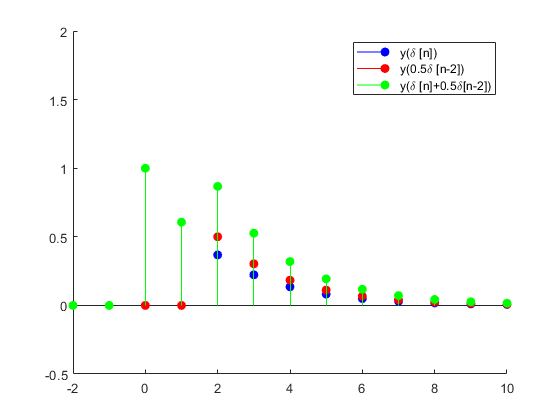

figure
clf
hold on
ylim([-0.5,2])
stem(n,h(n),'b','filled');
legend({'y(\delta [n])'})
pause(0.5)
stem(n,0.5*h(n-2),'r','filled');
legend({'y(\delta [n])', 'y(0.5\delta [n-2])'})
pause(0.5) 
stem(n,h(n)+0.5*h(n-2),'g','filled');
legend({'y(\delta [n])', 'y(0.5\delta [n-2])', 'y(\delta [n]+0.5\delta[n-2])'})

Por ejemplo:

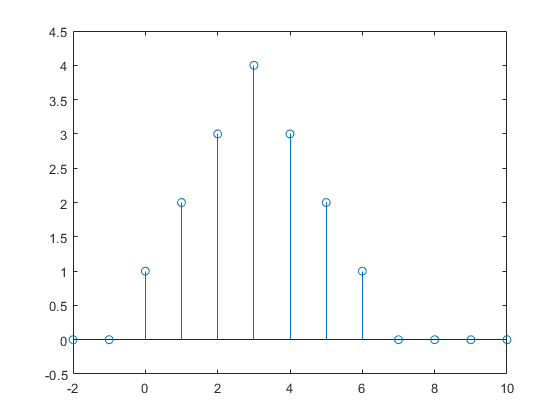

n = -2:10;
x = @(n) (n==0) + 2*(n==1) + 3*(n==2) + 4*(n==3) + 3*(n==4) + 2*(n==5) + (n==6);
figure(clf)
stem(n,x(n));
ylim([-0.5, 4.5])


$$x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack +2\delta \left\lbrack n-1\right\rbrack +3\delta \left\lbrack n-2\right\rbrack +4\delta \left\lbrack n-3\right\rbrack +3\delta \left\lbrack n-4\right\rbrack +2\delta \left\lbrack n-5\right\rbrack +\delta \left\lbrack n-6\right\rbrack$$



$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack$$


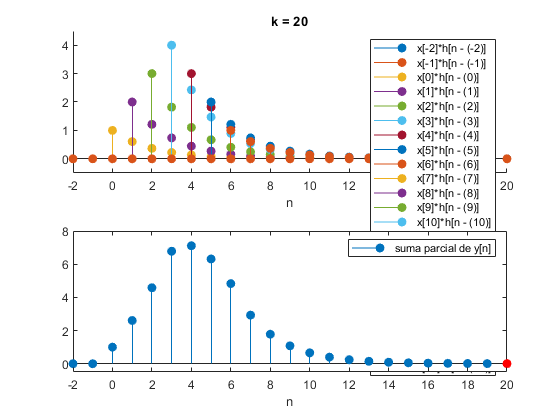

figure
clf
subplot(2,1,1)
hold on
clear Legends
ylim([-0.5,4.5])
xlim([-2,20])
xlabel('n')
subplot(2,1,2)
title('Suma parcial')
title('y[n] = conv(x[n],h[n])')
n = -2:20;
y = zeros(size(n));
for i = 1:length(n)
    subplot(2,1,1)
    title(['k = ' num2str(n(i))])
    stem(n,x(n(i))*h(n-n(i)),'filled')
    Legends{i} = ['x[', num2str(n(i)), ']*h[n - (', num2str(n(i)), ')]']; %#ok<SAGROW> 
    legend(Legends)
    subplot(2,1,2)
    y = y + x(n(i))*h(n-n(i));
    stem(n(1:i),y(1:i),'filled')
    hold on
    ylim([-0.5,8])
    xlim([-2,20])
    xlabel('n')
    stem(n(i),y(i),'r','filled')
    legend({'suma parcial de y[n]'})
    hold off
    pause(0.5) 
end 

## Interpretación gráfica


$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack$$


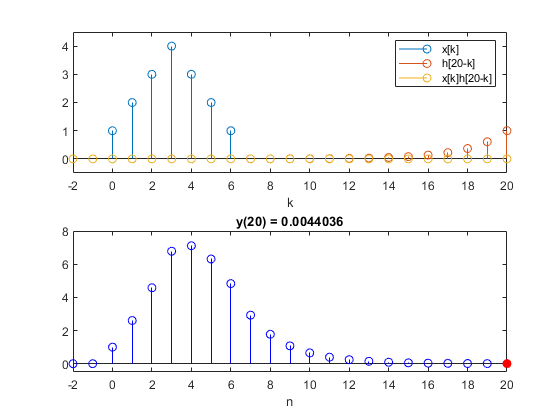

figure
for i = 1:length(n)
    subplot(2,1,1)
    stem(n,x(n))
    ylim([-0.5,4.5])
    xlim([-2,20])
    xlabel('k')
    hold on
    stem(n, h(n(i)-n))
    stem(n, x(n).*h(n(i)-n))
    legend({'x[k]', ['h[' num2str(n(i)) '-k]'], ['x[k]h[' num2str(n(i)) '-k]']})
    hold off
    subplot(2,1,2)
    stem(n(1:i),y(1:i),'b')
    ylim([-0.5,8])
    xlim([-2,20])
    title('y(n)')
    title(['y(' num2str(n(i)) ') = ' num2str(y(i))])
    xlabel('n')
    hold on
    stem(n(i),y(i),'r','filled')
    hold off
    pause(1)
end

# Respuesta al impulso (TC)


$$y\left(t\right)=T\left\lbrace \delta \left(t\right)\right\rbrace =h\left(t\right)$$


## Integral de convolución

Si queremos obtener la respuesta de un sistema $y\left(t\right)$ a una entrada arbitraria $x\left(t\right)$


$$y\left(t\right)=T\left\lbrace x\left(t\right)\right\rbrace$$


por la propiedad de *sifting* tenemos que$x\left(t\right)=\int_{-\infty }^{\infty } x\left(\tau \;\right)\delta \;\left(t-\tau \;\right)d\tau \;$


$$y\left(t\right)=T\left\lbrace \int_{-\infty }^{\infty } x\left(\tau \;\right)\delta \;\left(t-\tau \;\right)d\tau \;\right\rbrace$$


sabemos que $y\left(t\right)$ es *aditivo*


$$y\left(t\right)=\int_{-\infty }^{\infty } T\left\lbrace x\left(\tau \;\right)\delta \;\left(t-\tau \;\right)\right\rbrace d\tau \;$$


sabemos que $x\left(\tau \;\right)$no depende de $t$ y que $y\left(t\right)=T\left\lbrace x\left(t\right)\right\rbrace$ es *homogéneo*


$$y\left(t\right)=\int_{-\infty }^{\infty } x\left(\tau \;\right)T\left\lbrace \delta \left(t-\tau \right)\right\rbrace d\tau \;$$


sabemos que $T\left\lbrace \delta \left(t-\tau \right)\right\rbrace =h\left(t\right)$ y sabemos que $y\left(t\right)$ es *invariante en el tiempo*


$$y\left(t\right)=\int_{-\infty }^{\infty } x\left(\tau \;\right)h\left(t-\tau \;\right)d\tau \;=x\left(t\right)*h\left(t\right)$$


# Propiedad de integración


$$f\left(t\right)*u\left(t\right)=\int_{-\infty }^t f\left(\tau \right)d\tau$$


Por ejemplo:


$$f\left(t\right)=t\;u\left(t+2\right)$$



$$f\left(t\right)*u\left(t\right)=\int_{-\infty }^t \tau u\left(\tau +2\right)d\tau =\int_{-2}^t \tau d\tau ={\left(\frac{1}{2}\tau^2 \right)}_{\tau \;=-2}^{\tau =t} =\frac{1}{2}t^2 -\frac{1}{2}{\left(-2\right)}^2$$


# Ejercicios

## 1.1.a)


$$x\left(t\right)=2t^2$$
        
$$h\left(t\right)=e^{-t^2 }$$



$$y\left(t\right)=\int_{-\infty }^{\infty } x\left(\tau \;\right)h\left(t-\tau \;\right)d\tau \;\overset{\textrm{Conmutatividad}}{=} \int_{-\infty }^{\infty } h\left(\tau \right)x\left(t-\tau \right)d\tau \;$$



$$y\left(t\right)=\int_{-\infty }^{\infty } e^{-\tau {\;}^2 } 2{\left(t-\tau \;\right)}^2 d\tau \;\overset{\textrm{Expandiendo}\;\textrm{el}\;\textrm{binomio}}{=} 2\int_{-\infty }^{\infty } e^{-\tau {\;}^2 } \left(t^2 -2\tau t+\tau^2 \right)d\tau \;$$



$$=2\int_{-\infty }^{\infty } \left(e^{-\tau {\;}^2 } t^2 -2e^{-\tau {\;}^2 } \tau t+e^{-\tau {\;}^2 } \tau^2 \right)d\tau \;$$


Usando las pistas y notando que $e^{-\tau {\;}^2 } \tau$ es una función impar


$$=2t^2 \underset{\sqrt{\pi }}{\underbrace{\int_{-\infty }^{\infty } e^{-\tau {\;}^2 } d\tau \;} } -4t\underset{0}{\underbrace{\int_{-\infty }^{\infty } e^{-\tau {\;}^2 } \tau d\tau \;} } +2\underset{\frac{\sqrt{\pi }}{2}}{\underbrace{\int_{-\infty }^{\infty } e^{-\tau {\;}^2 } \tau^2 d\tau \;} }$$



$$=2\sqrt{\pi }t^2 +\sqrt{\pi \;}=\sqrt{\pi }\left(2t^2 +1\right)$$


## 1.1.d)


$$x\left(t\right)=\cos \left(2t\right)$$
        
$$h\left(t\right)=e^{-\left|t\;\right|}$$



$$y\left(t\right)=\int_{-\infty }^{\infty } x\left(\tau \;\right)h\left(t-\tau \;\right)d\tau \;\overset{\textrm{Conmutatividad}}{=} \int_{-\infty }^{\infty } h\left(\tau \;\right)x\left(t-\tau \;\right)d\tau \;$$



$$=\int_{-\infty }^{\infty } e^{-\left|\tau \;\right|} \cos \left(2\left(t-\tau \;\right)\right)d\tau \;$$


recordemos que:


$$\left|x\right|=\left\lbrace \begin{array}{cc}
x & \textrm{si}\;x\ge 0\\
-x & \textrm{si}\;x<0
\end{array}\right.$$



$$=\int_0^{\infty } e^{-\tau } \cos \left(2\left(t-\tau \right)\right)d\tau \;+\int_{-\infty }^0 e^{\tau } \cos \left(2\left(t-\tau \right)\right)d\tau \;$$


Sustitución $u=\tau -t$        $\textrm{du}=d\tau \;$


$$=\int_{-t}^{\infty } e^{-u-t} \cos \left(-2u\right)\textrm{du}\;+\int_{-\infty }^{-t} e^{u+t} \cos \left(-2u\right)\textrm{du}$$


como coseno es par


$$=\int_{-t}^{\infty } e^{-u-t} \cos \left(2u\right)\textrm{du}\;+\int_{-\infty }^{-t} e^{u+t} \cos \left(2u\right)\textrm{du}$$


sacando las constantes por propiedad de los exponentes $e^{a+b} =e^a e^b$


$$=e^{-t} \int_{-t}^{\infty } e^{-u} \cos \left(2u\right)\textrm{du}\;+e^t \int_{-\infty }^{-t} e^u \cos \left(2u\right)\textrm{du}$$


sustituyendo para la primera integral $v=-u$      $\textrm{dv}=-\textrm{du}$


$$=-e^{-t} \int_t^{-\infty } e^v \cos \left(2v\right)\textrm{dv}\;+e^t \int_{-\infty }^{-t} e^u \cos \left(2u\right)\textrm{du}$$


Usando como pista $\int e^x \cos \left(2x\right)\textrm{dx}=\frac{1}{5}e^x \left(2\sin \left(2x\right)+\cos \left(2x\right)\right)$ *véase *[https://socratic.org/questions/what-is-the-integral-of-int-e-x-cos-2x-dx](https://socratic.org/questions/what-is-the-integral-of-int-e-x-cos-2x-dx)


$$=-e^{-t} {\left(\frac{1}{5}e^v \left(2\sin \left(2v\right)+\cos \left(2v\right)\right)\right)}_{v=t}^{v=-\infty } +e^t {\left(\frac{1}{5}e^u \left(2\sin \left(2u\right)+\cos \left(2u\right)\right)\right)}_{v=-\infty }^{v=-t}$$



$$\begin{array}{l}
=-e^{-t} \left(\frac{1}{5}e^{-\infty \;} \left(2\sin \left(-\infty \right)+\cos \left(-\infty \right)\right)-\frac{1}{5}e^t \left(2\sin \left(2t\right)+\cos \left(2t\right)\right)\right)\\
\;\;\;\;+e^t \left(\frac{1}{5}e^{-t} \left(2\sin \left(-2t\right)+\cos \left(2t\right)\right)-\frac{1}{5}e^{-\infty } \left(2\sin \left(-\infty \right)+\cos \left(-\infty \right)\right)\right)
\end{array}$$



$$=\left(\frac{1}{5}\left(2\sin \left(2t\right)+\cos \left(2t\right)\right)\right)+\left(\frac{1}{5}\left(2\sin \left(-2t\right)+\cos \left(-2t\right)\right)\right)$$


recordando que $\sin \left(x\right)=-\sin \left(-x\right)$ y que $\cos \left(x\right)=\cos \left(-x\right)$


$$=\frac{2}{5}\cos \left(2t\right)$$


##  1.2.a)


$$\begin{array}{l}
x\left(t\right)=u\left(t\right)-u\left(t-2\right)\\
h\left(t\right)=2e^{-t} u\left(t\right)
\end{array}$$


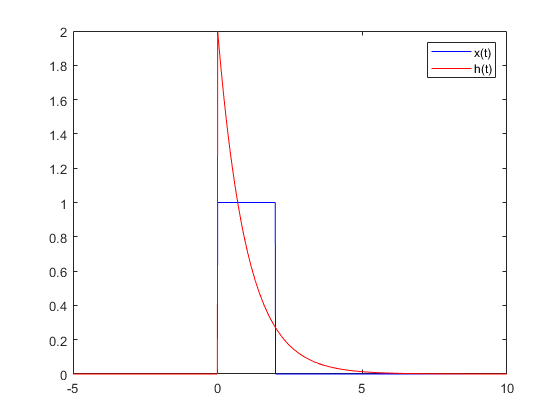

figure()
clf
dt = 0.01;
t = -5:dt:10;
x = @(t) (t>=0) - (t>=2);
h = @(t) 2*exp(-t).*(t>=0);
plot(t,x(t),'b',t,h(t),'r')
legend({'x(t)','h(t)'})


$$x\left(t\right)*h\left(t\right)=\int_{-\infty }^{\infty } x\left(\tau \right)h\left(t-\tau \;\right)d\tau$$


### Solución gráfica

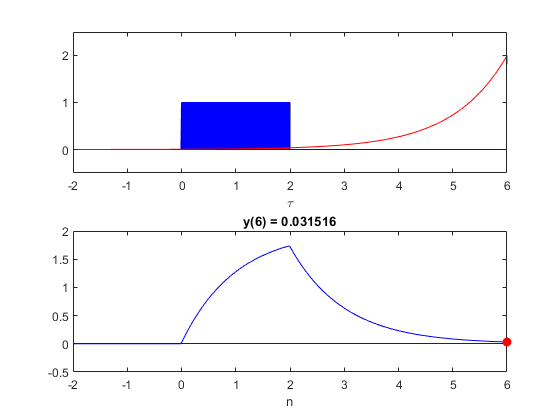

y = zeros(size(t));
for i = 1:length(t)
    y = y + x(t(i))*h(t-t(i))*dt;
end
figure
for i = find(t==-2):10:find(t==6)
    subplot(2,1,1)
    overlapt = 0:dt:min(t(i),2);
    overlapy = h(t(i)-overlapt);
    area(overlapt,overlapy==overlapy,'FaceColor','b');
    ylim([-0.5,2.5])
    xlim([-2,6])
    xlabel('\tau')
    hold on
    area(overlapt,overlapy,'FaceColor','r');
    plot(t,x(t),'b')
    plot(t,h(t(i)-t),'r')
    hold off
    subplot(2,1,2)
    plot(t(1:i),y(1:i),'b')
    ylim([-0.5,2])
    xlim([-2,6])
    title('y(t)')
    title(['y(' num2str(t(i)) ') = ' num2str(y(i))])
    xlabel('n')
    hold on
    stem(t(i),y(i),'r','filled')
    hold off
    pause(0.1)
end

Para $t<0$ las señales no se encuentran entonces el resultado sería 0

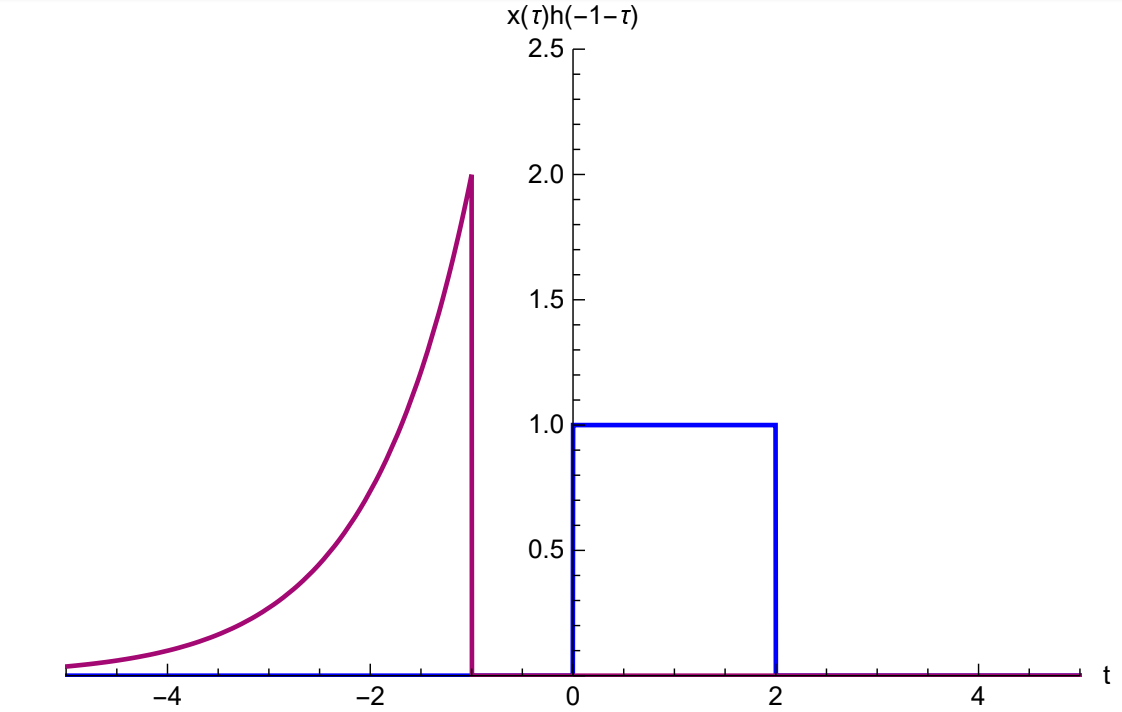


$$\int_{-\infty }^{\infty } x\left(\tau \right)h\left(t-\tau \;\right)d\tau \overset{t<0}{=} 0$$


Para $0\le t\le 2$las señales se encuentran entre 0 y $t$ entonces nos queda

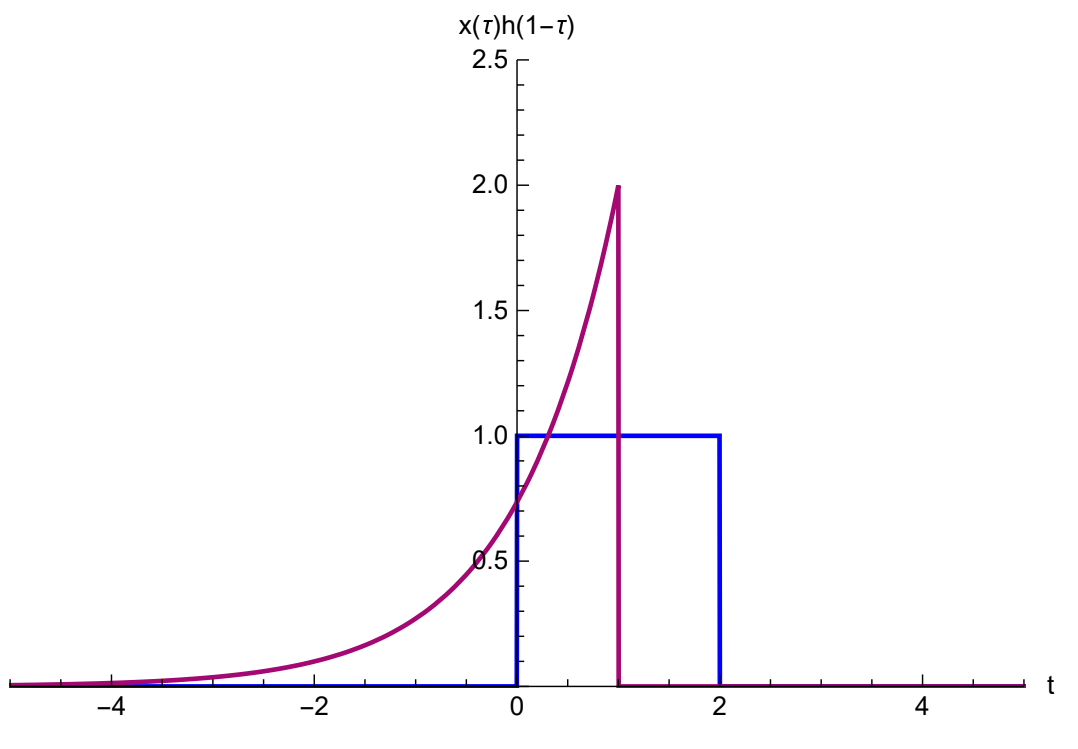


$$\int_{-\infty }^{\infty } x\left(\tau \right)h\left(t-\tau \;\right)d\tau \overset{0\le t\le 2}{=} \int_0^t \left(1\right)h\left(t-\tau \;\right)d\tau$$



$$\begin{array}{l}
h\left(t\right)=2e^{-t} u\left(t\right)\\
h\left(t-\tau \;\right)=2e^{-\left(t-\tau \;\right)} u\left(t-\tau \;\right)
\end{array}$$



$$=\int_0^t 2e^{-\left(t-\tau \;\right)} d\tau =2e^{-t} \int_0^t e^{\tau \;} d\tau =2e^{-t} \left(e^t -1\right)=2\left(1-e^{-t} \right)$$


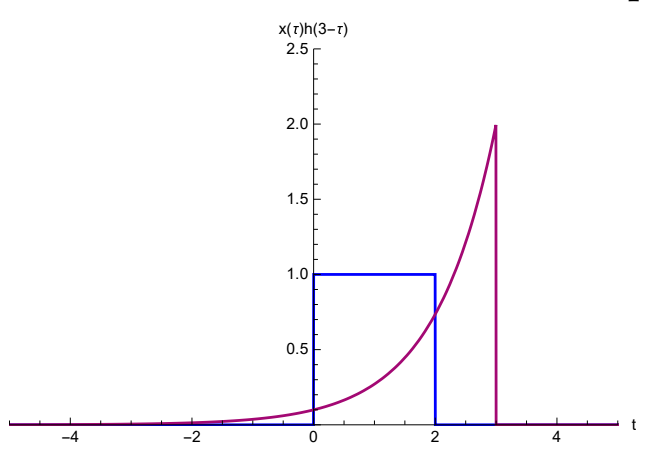


$$\int_{-\infty }^{\infty } x\left(\tau \right)h\left(t-\tau \;\right)d\tau \overset{t\ge 2}{=} \int_0^t \left(1\right)h\left(t-\tau \;\right)d\tau$$



$$=\int_0^t 2e^{-\left(t-\tau \;\right)} d\tau -\int_2^t 2e^{-\left(t-\tau \;\right)} d\tau$$



$$=2e^{-t} \left(\int_0^t e^{\tau } d\tau -\int_2^t e^{\tau } d\tau \right)$$



$$=2e^{-t} \left(\left(e^t -1\right)-\left(e^t -e^2 \right)\right)$$



$$=2e^{-t} \left(-1+e^2 \right)$$



$$=2e^{-t} \left(e^2 -1\right)$$


Juntando las respuestas nos queda

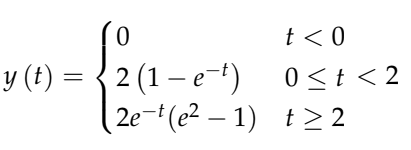

o lo que es equivalente:


$$y\left(t\right)=2\left(1-e^{-t} \right)\left(u\left(t\right)-u\left(t-2\right)\right)+2e^{-t} \left(e^2 -1\right)u\left(t-2\right)$$


### Solución analítica


$$y\left(t\right)=x\left(t\right)*h\left(t\right)=\left(u\left(t\right)-u\left(t-2\right)\right)*{2e}^{-t} u\left(t\right)=u\left(t\right)*{2e}^{-t} u\left(t\right)-u\left(t-2\right)*{2e}^{-t} u\left(t\right)$$


Veamos las dos convoluciones por aparte:

        
$$u\left(t\right)*{2e}^{-t} u\left(t\right)=\int_{-\infty }^{\infty } u\left(\tau \right)2e^{-\left(t-\tau \right)} u\left(t-\tau \;\right)d\tau$$


        Esta integral solo tiene valores entre 0 y $t>0$ (en caso contrario vale 0)

        
$$=2\int_0^t e^{-\left(t-\tau \right)} d\tau =2\int_0^t e^{\tau -t} d\tau ={2\left(e^{\tau -t} \right)}_{\tau =0}^{\tau =t} =2\left(e^{\left(t-t\right)} -e^{0-t} \right)=2\left(1-e^{-t} \right)$$


y luego:

        
$$u\left(t-2\right)*{2e}^{-t} u\left(t\right)=\int_{-\infty }^{\infty } u\left(\tau -2\right){2e}^{-\left(t-\tau \right)} u\left(t-\tau \right)d\tau$$


        Esta integral solo tiene valores entre 2 y $t$ si $t\ge 2$ (en caso contrario vale 0)

        
$$=\int_2^t {2e}^{-\left(t-\tau \right)} d\tau =2\int_2^t e^{\tau -t} d\tau ={2\left(e^{\tau -t} \right)}_{\tau =2}^{\tau =t} =2\left(e^{\left(t-t\right)} -e^{2-t} \right)=2\left(1-e^{2-t} \right)$$


Entonces nos queda la función definida por trozos:

    para $t<0$

    
$$y\left(t\right)=0$$


    para $0\le t<2$

    
$$y\left(t\right)=2\left(1-e^{-t} \right)$$


    para $t\ge 2$

    
$$y\left(t\right)=2\left(1-e^{-t} \right)-2\left(1-e^{2-t} \right)$$
 

    
$$y\left(t\right)=2\left(1-e^{-t} -1+e^{2-t} \right)$$


    
$$y\left(t\right)=2\left(-e^{-t} +e^{2-t} \right)$$


    
$$y\left(t\right)=2e^{-t} \left(e^2 -1\right)$$


que es la misma respuesta que obtuvimos empleando el método gráfico

## 2.1.a)

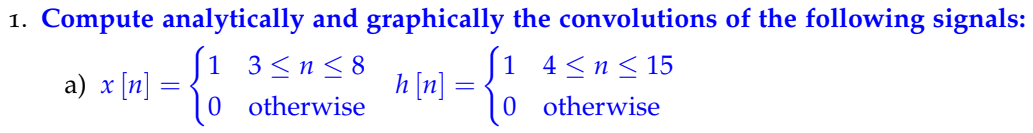


$$x\left\lbrack n\right\rbrack =u\left\lbrack n-3\right\rbrack -u\left\lbrack n-9\right\rbrack$$



$$h\left\lbrack n\right\rbrack =u\left\lbrack n-4\right\rbrack -u\left\lbrack n-16\right\rbrack$$


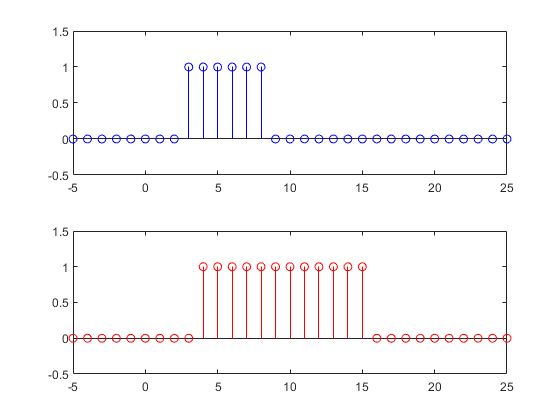

n = -5:25;
x = @(n) (n>=3) - (n>=9);
h = @(n) (n>=4) - (n>=16);

figure
subplot(2,1,1)
stem(n,x(n),'b')
ylim([-0.5,1.5])
subplot(2,1,2)
stem(n,h(n),'r')
ylim([-0.5,1.5])

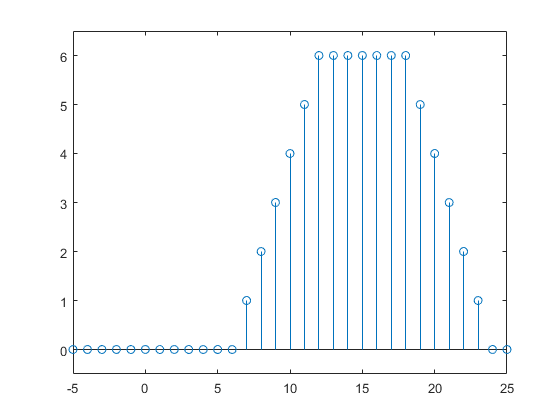

y = zeros(size(n));
for i = 1:length(n)
    y = y + x(n(i))*h(n-n(i));
end
figure
stem(n,y)
ylim([-0.5,6.5])

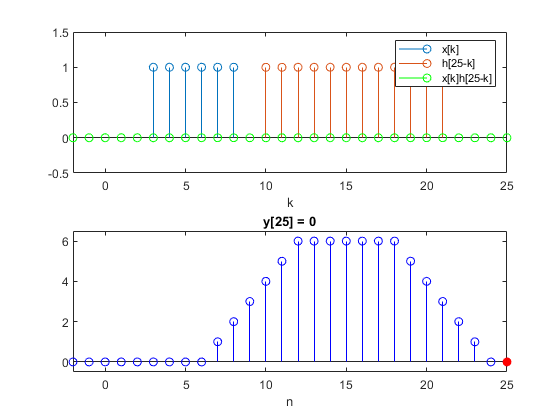

figure
for i = find(n==0):length(n)
    subplot(2,1,1)
    stem(n,x(n))
    ylim([-0.5,1.5])
    xlim([-2,25])
    xlabel('k')
    hold on
    stem(n, h(n(i)-n))
    xh = x(n).*h(n(i)-n);
    stem(n,xh,'g')
    legend({'x[k]', ['h[' num2str(n(i)) '-k]'], ['x[k]h[' num2str(n(i)) '-k]']})
    hold off
    subplot(2,1,2)
    stem(n(1:i),y(1:i),'b')
    ylim([-0.5,6.5])
    xlim([-2,25])
    title('y[n]')
    title(['y[' num2str(n(i)) '] = ' num2str(y(i))])
    xlabel('n')
    hold on
    stem(n(i),y(i),'r','filled')
    hold off
    pause(1)
end

### Solución gráfica


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack$$


Podemos ver que$x\left\lbrack k\right\rbrack$tiene valores entre 3 y 8 y $h\left\lbrack n-k\right\rbrack$ tiene valores entre $n-15$ y $n-4$


$$3=n-4\to n=7$$


Para $n<7$ las señales no se encuentran entonces el resultado sería 0

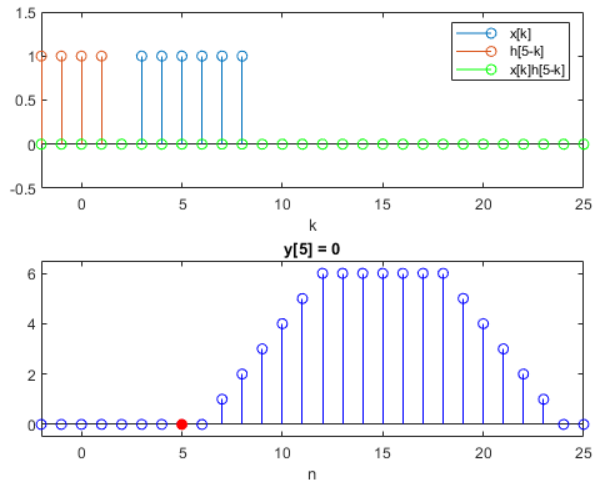


$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack \overset{n<7}{=} 0$$


Para $7\le n\le 12$ $h\left\lbrack n-k\right\rbrack$ alcanza a $x\left\lbrack k\right\rbrack$, se van superponiendo cada vez más muestras y los límites son entre 3 y $n-4$:


$$8=n-4\to n=12$$


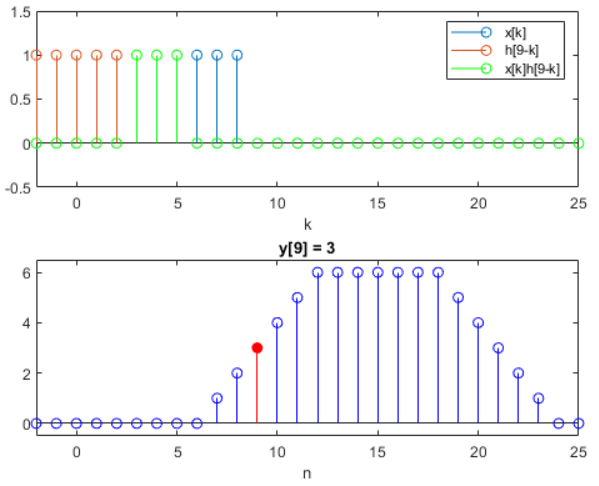


$$\sum_{n=a}^b 1=b-a+1$$



$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack \overset{7\le n\le 12}{=} \sum_{k=3}^{n-4} \left(1\right)\left(1\right)=n-4-3+1=n-6$$


Para $13\le n\le 18$ $h\left\lbrack n-k\right\rbrack$ y $x\left\lbrack k\right\rbrack$ están completamente superpuestas y los límites son entre 3 y 8:


$$3=n-15\to n=18$$


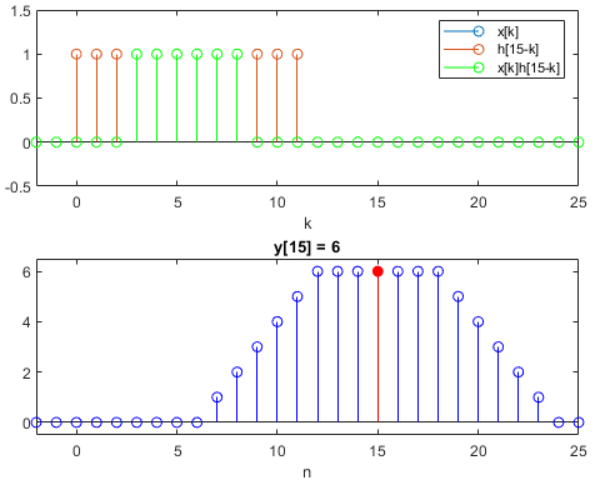

 
$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack \overset{13\le n\le 18}{=} \sum_{k=3}^8 \left(1\right)\left(1\right)=8-3+1=6$$


Para $19\le n\le 23$ $h\left\lbrack n-k\right\rbrack$ se empieza a separar de $x\left\lbrack k\right\rbrack$, se van superponiendo cada vez menos muestras y los límites son entre n-15 y 8


$$n-15=8\to n=23$$


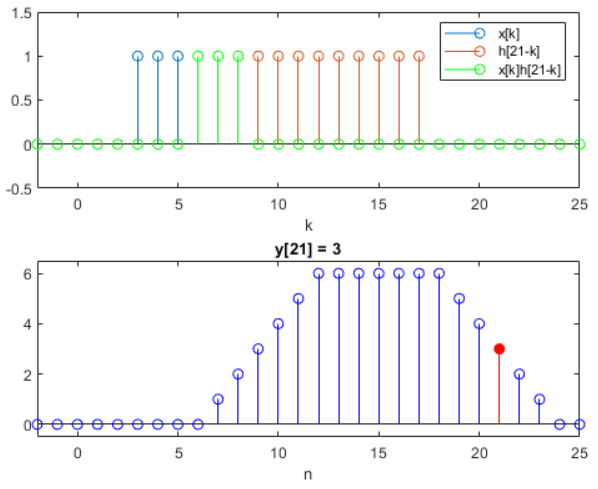


$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack \overset{19\le n\le 23}{=} \sum_{k=n-15}^8 \left(1\right)\left(1\right)=8-n+15+1=24-n$$


Para $n\ge 24$ las señales no se intersectan entonces la señal se mantiene en 0:

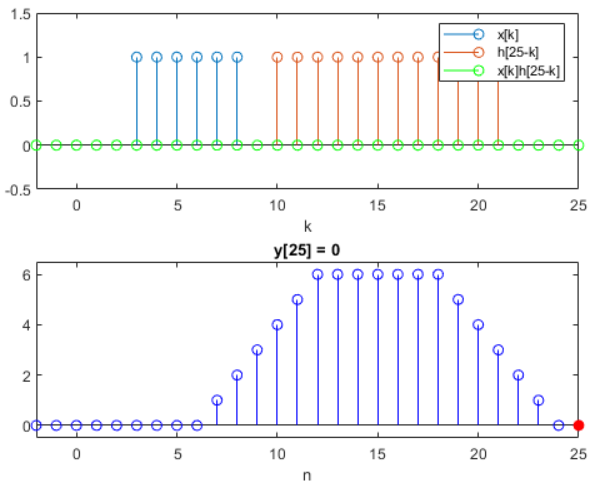


$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack \overset{n\ge 24}{=} 0$$


### Solución analítica


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack =\left(u\left\lbrack n-3\right\rbrack -u\left\lbrack n-9\right\rbrack \right)*\left(u\left\lbrack n-4\right\rbrack -u\left\lbrack n-16\right\rbrack \right)=\sum_{k=-\infty }^{\infty } \left(u\left\lbrack k-3\right\rbrack -u\left\lbrack k-9\right\rbrack \right)\left(u\left\lbrack n-k-4\right\rbrack -u\left\lbrack n-k-16\right\rbrack \right)$$



$$=\sum_{k=-\infty }^{\infty } u\left\lbrack k-3\right\rbrack u\left\lbrack n-k-4\right\rbrack -u\left\lbrack k-9\right\rbrack u\left\lbrack n-k-4\right\rbrack -u\left\lbrack k-3\right\rbrack u\left\lbrack n-k-16\right\rbrack +u\left\lbrack k-9\right\rbrack u\left\lbrack n-k-16\right\rbrack$$



$$=\sum_{k=-\infty }^{\infty } u\left\lbrack k-3\right\rbrack u\left\lbrack n-k-4\right\rbrack -\sum_{k=-\infty }^{\infty } u\left\lbrack k-9\right\rbrack u\left\lbrack n-k-4\right\rbrack -\sum_{k=-\infty }^{\infty } u\left\lbrack k-3\right\rbrack u\left\lbrack n-k-16\right\rbrack +\sum_{k=-\infty }^{\infty } u\left\lbrack k-9\right\rbrack u\left\lbrack n-k-16\right\rbrack$$



$$=\sum_{k=3}^{n-4} \left(1\right)\left(1\right)-\sum_{k=9}^{n-4} \left(1\right)\left(1\right)-\sum_{k=3}^{n-16} \left(1\right)\left(1\right)+\sum_{k=9}^{n-16} \left(1\right)\left(1\right)$$



$$3\le n-4\to n\ge 7$$



$$9\le n-4\to n\ge 13$$



$$3\le n-16\to n\ge 19$$



$$9\le n-16\to n\ge 25$$


Cada una de estas sumatorias solo tiene sentido (es distinta de cero) cuando el límite superior es mayor que el inferior

        
$$\begin{array}{l}
n-k-4\ge 0\to n\ge k+4\\
n-k-15\ge 0\to n\ge k+16
\end{array}$$


El primer término sólo tendría valores para $n\ge 7$, el segundo para $n\ge 13$, el tercero para $n\ge 19$ y el último para $n\ge 25$ entonces se puede escribir la función acompañando cada término con un escalón que lo active cuando su condición correspondiente se cumpla:


$$\begin{array}{l}
=\left(n-4-3+1\right)u\left\lbrack n-7\right\rbrack -\left(n-4-9+1\right)u\left\lbrack n-13\right\rbrack -\left(n-16-3+1\right)u\left\lbrack n-19\right\rbrack +\left(n-16-9+1\right)u\left\lbrack n-25\right\rbrack \\
=\left(n-6\right)u\left\lbrack n-7\right\rbrack -\left(n-12\right)u\left\lbrack n-13\right\rbrack -\left(n-18\right)u\left\lbrack n-19\right\rbrack +\left(n-24\right)u\left\lbrack n-25\right\rbrack 
\end{array}$$


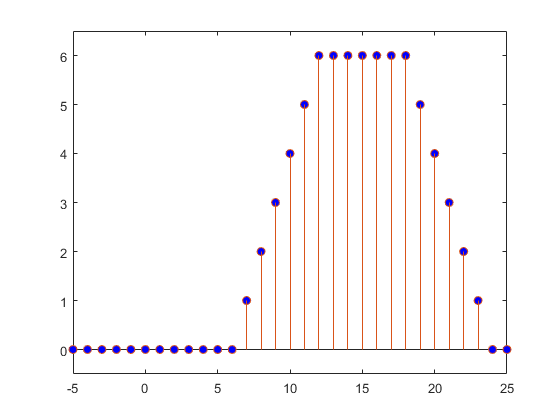

y2 = @(n) (n-6).*(n>=7)-(n-12).*(n>=13)-(n-18).*(n>=19)+(n-24).*(n>=25);
figure
stem(n,y,'b','filled')
hold on
stem(n,y2(n))
ylim([-0.5,6.5])

## 2.2)

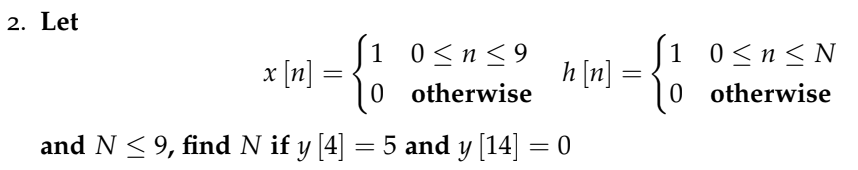


$$14\ge 10+\left(N+1\right)-1=10+N\to N\le 4$$



$$x\left\lbrack n\right\rbrack =u\left\lbrack n\right\rbrack -u\left\lbrack n-10\right\rbrack$$



$$h\left\lbrack n\right\rbrack =u\left\lbrack n\right\rbrack -u\left\lbrack n-\left(N+1\right)\right\rbrack$$


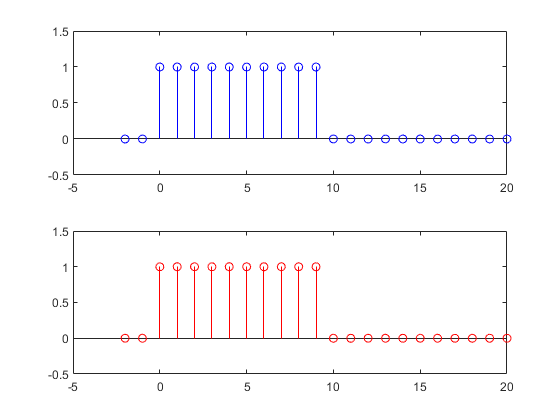

n = -2:20;
x = @(n) (n>=0) - (n>=10);
N = 9;
h = @(n) (n>=0) - (n>=N+1);
figure
subplot(2,1,1)
stem(n,x(n),'b')
ylim([-0.5,1.5])
subplot(2,1,2)
stem(n,h(n),'r')
ylim([-0.5,1.5])

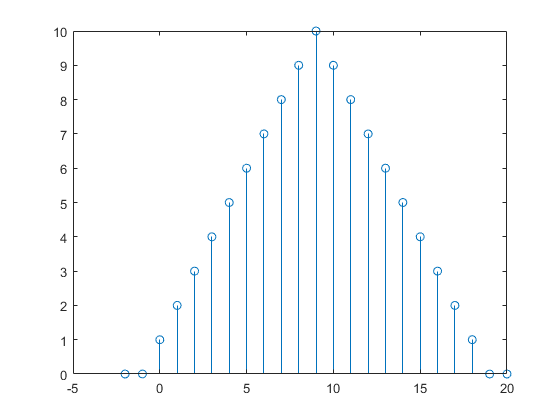

y = zeros(size(n));
for i = 1:length(n)
    y = y + x(n(i))*h(n-n(i));
end
figure
stem(n,y)

%ylim([-0.5,6])

# Causalidad

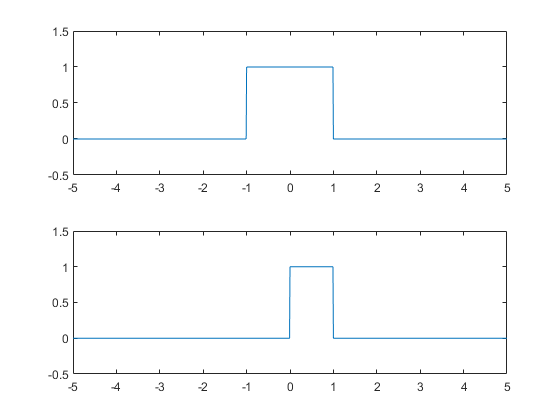

dt = 0.01;
t = -5:dt:5;
h = @(t) (t>=-1)-(t>=1);
x = @(t) (t>=0)-(t>=1);
figure
subplot(2,1,1)
plot(t,h(t))
ylim([-0.5,1.5])
subplot(2,1,2)
plot(t,x(t))
ylim([-0.5,1.5])

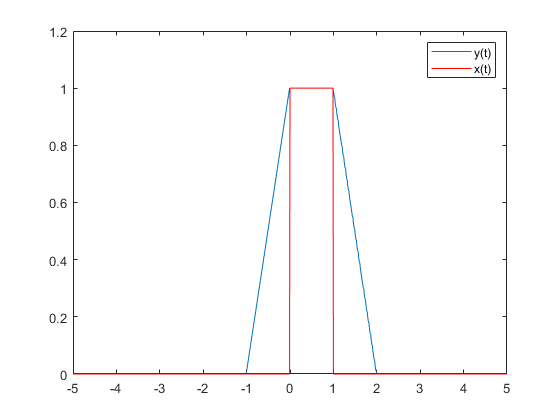

y = zeros(size(t));
for i = 1:length(t)
    y = y + x(t(i))*h(t-t(i))*dt;
end
figure
plot(t,y)
hold on
plot(t,x(t),'r')
legend({'y(t)','x(t)'})

# BIBO estabilidad

Una función $x\left(t\right)$ se dice **acotada** si existe un escalar $B<\infty$ tal que $\left|x\left(t\right)\right|\le B$ para todo $t$

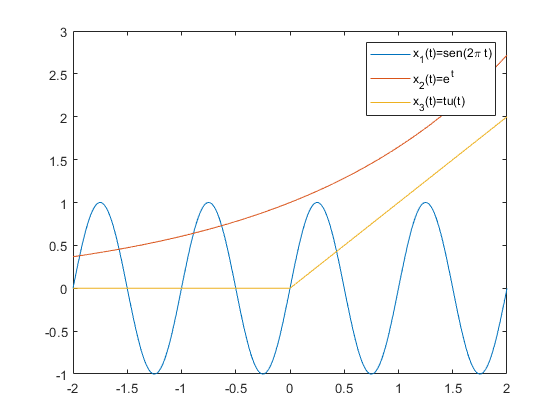

t=-2:0.001:2;
figure()
plot(t,sin(2*pi*t))
hold on
plot(t,exp(0.5*t))
plot(t,t.*(t>=0))
legend({'x_1(t)=sen(2\pi t)','x_2(t)=e^t','x_3(t)=tu(t)'})

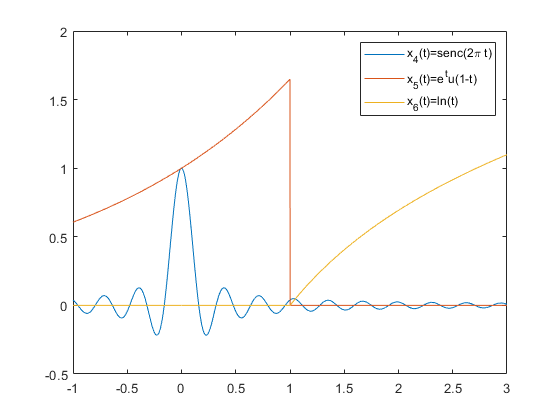

t=-1:0.001:3;
figure()
plot(t,sinc(2*pi*t))
hold on
plot(t,exp(0.5*t).*(1-t>=0))
plot(t,log(t).*(t>=1))
legend({'x_4(t)=senc(2\pi t)','x_5(t)=e^tu(1-t)','x_6(t)=ln(t)'})

Un sistema se dice **BIBO estable** si para cualquier entrada acotada (*Bounded Input*) produce una salida acotada (*Bounded Output*)

## Teorema de BIBO estabilidad para sistemas LTI

Un sistema LTI es BIBO estable si y solo si su respuesta al impulso $h\left(t\right)$ es absolutamente integrable (absolutamente sumable), es decir si existe una cota $M$tal que $\int_{-\infty }^{\infty } \left|h\left(t\right)\right|\mathrm{dt}\le M$


$$h\left(t\right)=\int_{-\infty }^{\infty } \delta \left(\tau \right)x\left(t-\tau \right)d\tau =\int_{-\infty }^t \delta \left(\tau \right)d\tau =u\left(t\right)$$



$$h\left(t\right)=\frac{d}{\textrm{dt}}\delta \left(t\right)=\delta^{\prime } \left(t\right)$$
